info = audiodevinfo

info = struct with fields:
     input: [1×2 struct]
    output: [1×3 struct]


nDevices = audiodevinfo(1)

nDevices = 2

% name = audiodevinfo(1,-1)
DriverVersion = audiodevinfo(1,0,"DriverVersion")

DriverVersion = 'Windows DirectSound'

support = audiodevinfo(1,2,44100,16,1)

support = logical
   0


%devID = audiodevinfo(1,"devName")
suppDevID = audiodevinfo(1,44100,16,1)

suppDevID = 0

%record audio and plot
Fs = 44100; 
nBits = 8; 
nChannels = 1; 
ID = -1;       % default audio input device 
Ts = 1/Fs;
recObj = audiorecorder(Fs,nBits,nChannels,ID);

No audio input device found on this system.


disp("Begin speaking.") 

recDuration = 5; % record for 5 seconds
recordblocking(recObj,recDuration);

disp("End of recording.")
y = getaudiodata(recObj);

%Graph from Project 1
plot(0:1/Fs:recDuration-1/Fs, y);
title('Audio Signal');
xlabel('Time (seconds)');
ylabel('Signal Amplitude');

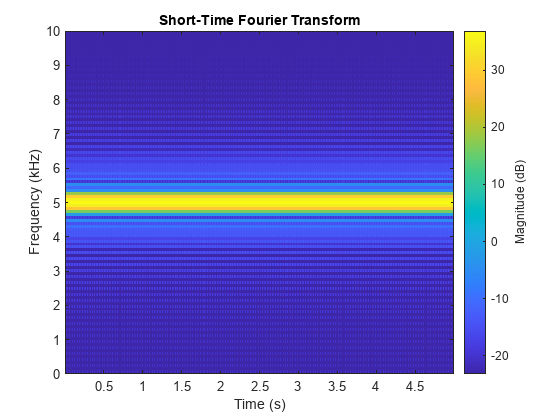

%sin wave function of original audio
signalFrequency = 5000; % Hz
%t = linspace(0, 5, 256); % seconds
t = 0:Ts:5;
sinWave = sin(2*pi*signalFrequency*t);

%Play sound at Fs
sound(sinWave,Fs)

%create .wav file for sine wave of original audio
filename = './ece2312_sinetone.wav';
audiowrite(filename,sinWave,Fs);

% of spectrogram .wav file for sine wave of original audio
stft(sinWave,Fs,Window = kaiser(256,5),OverlapLength=220, FFTLength =512);
ylim([0 10]) %can play around with limits to highlight speech section

% sine wave of chirp at varied frequencies

t = 0:Ts:5;
fstart = 0;
fend = 8000;
chirpFrequency = linspace(fstart, fend, length(t))

chirpFrequency = 1.0e+03 *

         0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0013    0.0013    0.0013    0.0014    0.0014    0.0015    0.0015    0.0015    0.0016    0.0016    0.0016    0.0017    0.0017    0.0017    0.0018



 %from 0Hz-8000Hz
a = sin(2*pi*chirpFrequency.*t)

a =          0    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0006    0.0007    0.0009    0.0010    0.0012    0.0013    0.0015    0.0017    0.0019    0.0021    0.0023    0.0025    0.0027    0.0030    0.0032    0.0035    0.0038    0.0041    0.0043    0.0047    0.0050    0.0053    0.0056    0.0060    0.0063    0.0067    0.0071    0.0075    0.0079    0.0083    0.0087    0.0091    0.0096    0.0100    0.0105    0.0109    0.0114    0.0119    0.0124


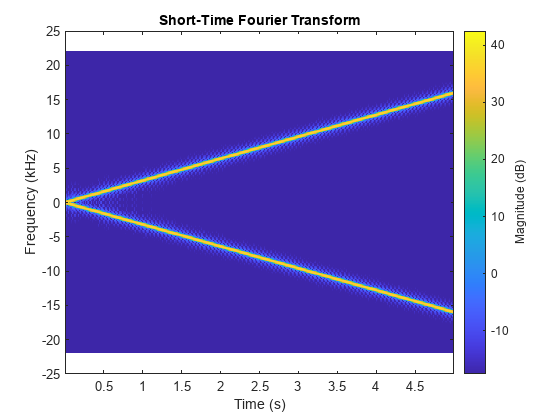


%Play sound at Fs
sound(a,Fs)

%create  .wav file for sine wave of chirp
filename = './ece2312-chirp.wav';
audiowrite(filename,a,Fs);

%plot .wav file for sine wave of chirp
stft(a,Fs,Window = kaiser(256,5),OverlapLength=220, FFTLength =512);
ylim([-25 25]) %can play around with limits to highlight speech section

%CETK 5 sine tones

% Start with the tone. (Pinkish-red) - D
% Up a full tone. (Orange) - E
% Down a major third. (Purple) - C 
% Down an octave. (Yellow) - C (an octave lower)
% Up a perfect fifth. (White) - G
% Using websites
    %https://www.liutaiomottola.com/formulae/freqtab.htm 
    %https://musictales.club/article/five-tones-spielbergs-alien-language
    %https://www.youtube.com/watch?v=kpsEqINeMS4

t = linspace(0, 5); % seconds

%Within 0Hz - 8000Hz range    
% Tone frequency, in Hertz. must be less than .5 * Fs.
ftone1 = 932.328; % Hz Bb
ftone2 = 1046.502;  % Hz  C
ftone3 = 830.609;  % Hz  Ab
ftone4 = 415.305;  % Hz  Ab octave lower 
ftone5 = 622.254;  % Hz  Eb

%we chose these times below as an approximation of the times
%represented in the video
timeDuration1 = .3

timeDuration1 = 0.3000

timeDuration2 = .5

timeDuration2 = 0.5000

timeDuration3 = 1

timeDuration3 = 1

timeDuration4 = 1.5

timeDuration4 = 1.5000


a = sin(linspace(0, timeDuration1*ftone1*2*pi, round(timeDuration1*Fs)));
b = sin(linspace(0, timeDuration2*ftone2*2*pi, round(timeDuration2*Fs)));
c = sin(linspace(0, timeDuration3*ftone3*2*pi, round(timeDuration3*Fs)));
d = sin(linspace(0, timeDuration2*ftone4*2*pi, round(timeDuration2*Fs)));
e = sin(linspace(0, timeDuration4*ftone5*2*pi, round(timeDuration4*Fs)));

% 
% sound(a, Fs);       % Play sound at sampling rate Fs
% pause(.5)
% % sound(halfSecSilence, Fs);
% sound(b, Fs);
% pause (.5)
% sound(c, Fs);
% pause (1)
% sound(d, Fs);         %maria we need to make this into one
% pause (.45)
% sound(e, Fs);

cetkSineWave = [a,b,c,d,e]

cetkSineWave =          0    0.1325    0.2626    0.3881    0.5067    0.6164    0.7153    0.8016    0.8737    0.9304    0.9708    0.9940    0.9997    0.9878    0.9585    0.9123    0.8501    0.7728    0.6819    0.5790    0.4659    0.3446    0.2173    0.0861   -0.0467   -0.1786   -0.3073   -0.4306   -0.5464   -0.6525   -0.7471   -0.8286   -0.8954   -0.9465   -0.9809   -0.9980   -0.9976   -0.9795   -0.9442   -0.8922   -0.8246   -0.7423   -0.6471   -0.5404   -0.4242   -0.3005   -0.1715   -0.0395    0.0932    0.2243


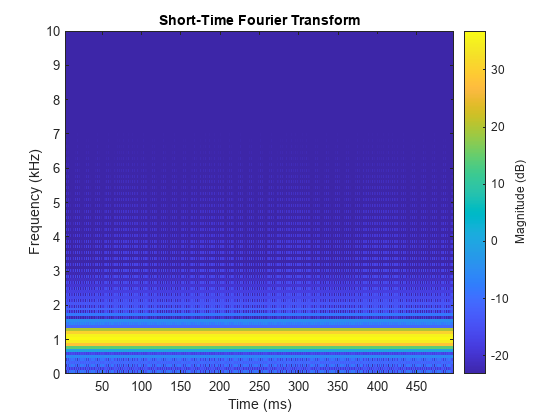

sound(cetkSineWave, Fs)

%create  .wav file for sine wave of cetk
filename = './ece2312-cetk.wav';
audiowrite(filename,cetkSineWave,Fs);

% % %plot .wav file for sine wave of cetk
 stft(b,Fs,Window = kaiser(256,5),OverlapLength=220, FFTLength =512);
 %[s f t] = spectrogram()
 ylim([0 10]) %can play around with limits to highlight speech section

% %Combining Sound files

signalFrequency = 5000; % Hz
%t = 0:Ts:3; % seconds
t = linspace(0, 3, 132300); % seconds

[oldWav, Fs] = audioread("ece2312_dog.wav")

oldWav =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Fs = 44100

oldWav = oldWav.'

oldWav =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sinWave = sin(2*pi*signalFrequency*t)

sinWave =          0    0.6536    0.9894    0.8439    0.2879   -0.4081   -0.9056   -0.9626   -0.5515    0.1279    0.7451    0.9998    0.7683    0.1630   -0.5215   -0.9524   -0.9201   -0.4402    0.2537    0.8243    0.9939    0.6801    0.0355   -0.6264   -0.9836   -0.8624   -0.3217    0.3754    0.8899    0.9716    0.5807   -0.0926   -0.7209   -0.9986   -0.7905   -0.1980    0.4909    0.9410    0.9334    0.4718   -0.2193   -0.8037   -0.9972   -0.7057   -0.0709    0.5983    0.9765    0.8798    0.3551   -0.3423


combinedWave = sinWave + oldWav

combinedWave =          0    0.6536    0.9894    0.8439    0.2879   -0.4081   -0.9056   -0.9626   -0.5515    0.1279    0.7451    0.9998    0.7683    0.1630   -0.5215   -0.9524   -0.9201   -0.4402    0.2537    0.8243    0.9939    0.6801    0.0355   -0.6264   -0.9836   -0.8624   -0.3217    0.3754    0.8899    0.9716    0.5807   -0.0926   -0.7209   -0.9986   -0.7905   -0.1980    0.4909    0.9410    0.9334    0.4718   -0.2193   -0.8037   -0.9972   -0.7057   -0.0709    0.5983    0.9765    0.8798    0.3551   -0.3423



sound (combinedWave, Fs)
% sound (sinWave, Fs)

%create  .wav file for combined sound waves
filename = './ece2312-speechchirp.wav';
audiowrite(filename,combinedWave,Fs);

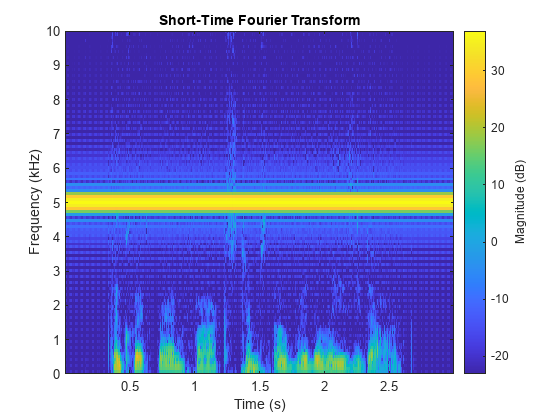


%plot .wav file for combined sound waves
stft(combinedWave,Fs,Window = kaiser(256,5),OverlapLength=220, FFTLength =512);
ylim([0 10]) %can play around with limits to highlight speech section

%Designing a lowpass

filter = lowpass(combinedWave, 4000, Fs, ImpulseResponse="iir",Steepness=.95)

filter =    -0.0226   -0.0405   -0.0534   -0.0570   -0.0494   -0.0321   -0.0092    0.0135    0.0304    0.0376    0.0340    0.0213    0.0038   -0.0132   -0.0249   -0.0284   -0.0231   -0.0112    0.0032    0.0157    0.0226    0.0223    0.0152    0.0039   -0.0078   -0.0164   -0.0194   -0.0161   -0.0080    0.0021    0.0111    0.0161    0.0158    0.0105    0.0022   -0.0064   -0.0125   -0.0144   -0.0117   -0.0053    0.0024    0.0090    0.0124    0.0117    0.0074    0.0009   -0.0056   -0.0100   -0.0110   -0.0084


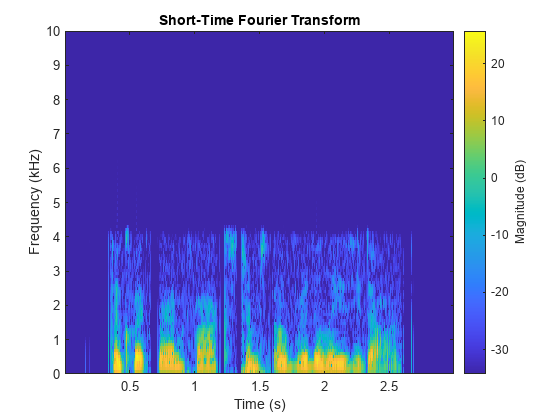


sound (filter, Fs)

%create  .wav file for lowpass filter
filename = './ece2312-filteredspeechsine.wav';
audiowrite(filename,filter,Fs);

%plot .wav file for lowpass filter
stft(filter,Fs,Window = kaiser(256,5),OverlapLength=220, FFTLength =512);
ylim([0 10]) %can play around with limits to highlight speech section

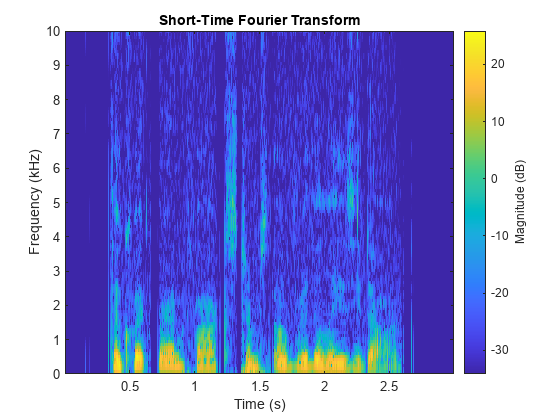

% Stereo Fun

scale = 10^(-6/10);

L = oldWav; %original audio, left speaker
R = combinedWave*scale; %%attenated by -6 db, right speaker

sound (L, Fs)
sound (R, Fs)

filename = './ece2312-stereospeechsine.wav';
audiowrite(filename,cetkSineWave,Fs);

%Spectrograms of audio channels
stft(L,Fs,Window = kaiser(256,5),OverlapLength=220, FFTLength =512);
ylim([0 10]) %can play around with limits to highlight speech section

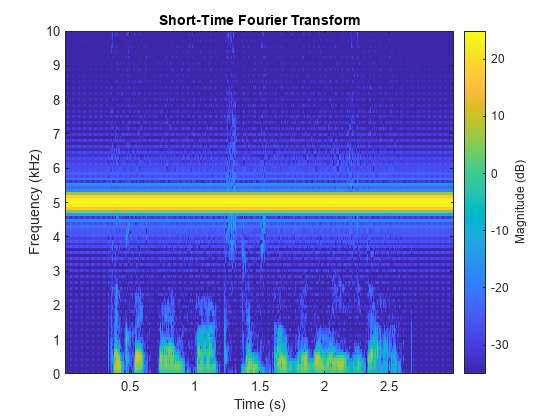

stft(R,Fs,Window = kaiser(256,5),OverlapLength=220, FFTLength =512);
ylim([0 10]) %can play around with limits to highlight speech section